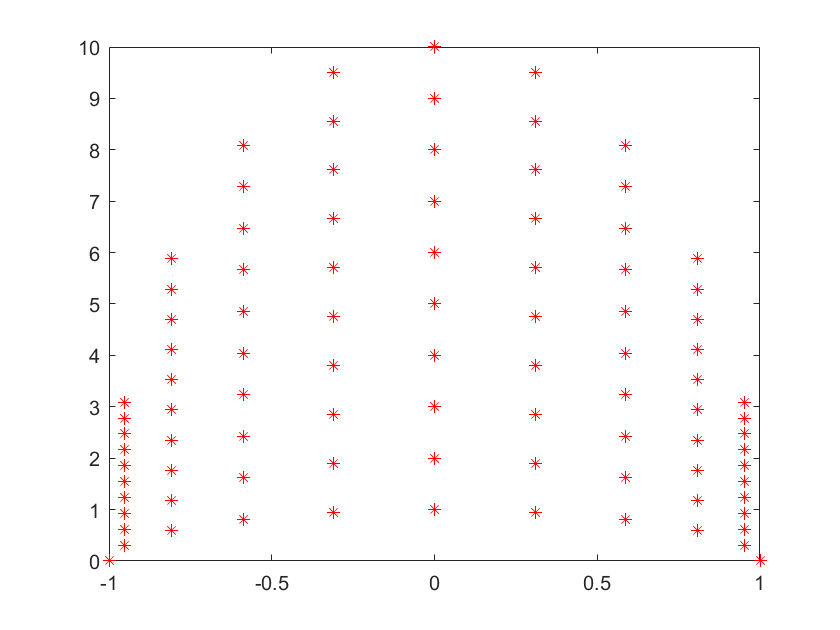

clear all, clc, close all
N      = 20; %Number of *
Nf= 10; %number of frames
n      = 1:N/2;
tao    = n/N;
v=0;
X=rand(2*length(tao),Nf+1);%Matriz random
x = abs(cos(2*pi*tao))'; 
    x = [x;-x];
X(:,1)= x; %Reemplazar la primera columna de X por x.

for t = 1:Nf
    
    yt = abs(t*sin(2*pi*tao))';
    yt = [yt;yt];
    yt = yt + v*rand(length(yt),1);
    X(:,t+1) = yt; %La columna t+1 es reemplazado por yt. 
    plot(x,yt,'*r')
    axis([-1 1 0 Nf])
    hold on
    pause(0.2)
end

X

X =     0.9511    0.3090    0.6180    0.9271    1.2361    1.5451    1.8541    2.1631    2.4721    2.7812    3.0902
    0.8090    0.5878    1.1756    1.7634    2.3511    2.9389    3.5267    4.1145    4.7023    5.2901    5.8779
    0.5878    0.8090    1.6180    2.4271    3.2361    4.0451    4.8541    5.6631    6.4721    7.2812    8.0902
    0.3090    0.9511    1.9021    2.8532    3.8042    4.7553    5.7063    6.6574    7.6085    8.5595    9.5106
    0.0000    1.0000    2.0000    3.0000    4.0000    5.0000    6.0000    7.0000    8.0000    9.0000   10.0000
    0.3090    0.9511    1.9021    2.8532    3.8042    4.7553    5.7063    6.6574    7.6085    8.5595    9.5106
    0.5878    0.8090    1.6180    2.4271    3.2361    4.0451    4.8541    5.6631    6.4721    7.2812    8.0902
    0.8090    0.5878    1.1756    1.7634    2.3511    2.9389    3.5267    4.1145    4.7023    5.2901    5.8779
    0.9511    0.3090    0.6180    0.9271    1.2361    1.5451    1.8541    2.1631    2.4721    2.7812    3.09

%k=2;
%lab=kmeans(X,k);
%imagesc(lab)
%plot(lab)

